# Feedforward neural network

BE CAREFUL, THIS SCRIPT CAN OVERWRITE FILES

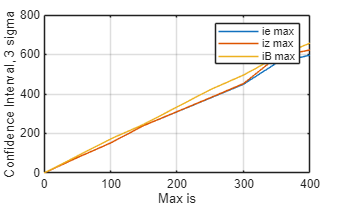

idx = 5

beta =     2.5747
    1.5202


ie_max = 382.6277

ie_max = 379.5059

beta =    -3.3579
    1.5881


iz_max = 393.6622

iz_max = 381.0048

beta =     2.8270
    1.6531


iB_max = 416.1112

iB_max = 421.8935

ix_max = 200

iy_max = 280

is_max = 250

vo_max = 6000

C = 0.0050

vc_mean_ref = 18000

E = 8.9100e+05

VB = 12000

IB = 500

IE = 500

VO = 6000

IS = 250

Xmax = 1.0e+05 *

    8.9100
    8.9100
    8.9100
    8.9100
    8.9100
    8.9100
    8.9100
    8.9100
    8.9100
    0.0770
    0.0770
    0.0770
    0.0550
    0.0550
    0.0550


Ymax =          500
         500
         500
         500
        6000


Nbuffer_variables = 27

Nsamples = 10000

Ninputs = 21

Noutputs = 5

ans =           21       10000


ans =            5       10000


ans = 279.9842

Ninputs = 21

Nsamples = 10000

Noutputs = 5

Nsamples = 10000

Nsamples = 10000

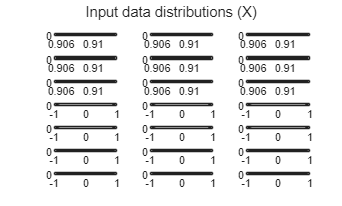

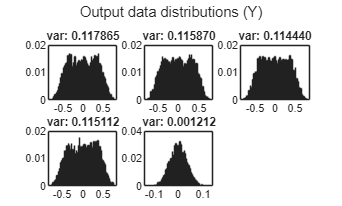

run('DataPreparation.mlx');

save_net = true; % Overwrite current feedforward architecture

## Architecture

argsFFNN                  = struct();
argsFFNN.Ninputs          = Ninputs;
argsFFNN.Noutputs         = Noutputs;
argsFFNN.Nlayers          = 1;
argsFFNN.Nneurons         = 3*Ninputs;
argsFFNN.HiddenActivation = 'relu';
argsFFNN.OutputActivation = 'tanh';
argsFFNN.Dropout          = 0;
argsFFNN.WinitFcn         = 'glorot';
argsFFNN.BinitFcn         = 'glorot';
argsFFNN.BatchNorm        = true;
argsFFNN.TrainBias        = true;

FFnet = FFNNgenerator(argsFFNN)

FFnet =   dlnetwork with properties:

         Layers: [7×1 nnet.cnn.layer.Layer]
    Connections: [6×2 table]
     Learnables: [6×3 table]
          State: [2×3 table]
     InputNames: {'input'}
    OutputNames: {'tanh'}
    Initialized: 1
  View summary with summary.

## Training

argsFFNNtrain                     = struct();
argsFFNNtrain.net                 = FFnet;
argsFFNNtrain.X_train             = dlX_tr;
argsFFNNtrain.Y_train             = dlY_tr;
argsFFNNtrain.X_val               = dlX_val;
argsFFNNtrain.Y_val               = dlY_val;
argsFFNNtrain.InitialLearningRate = 1e-2;
argsFFNNtrain.FinalLearningRate   = 1e-6;
argsFFNNtrain.Plots               = 'training-progress'

argsFFNNtrain = struct with fields:
                    net: [1×1 dlnetwork]
                X_train: [21×8000 dlarray]
                Y_train: [5×8000 dlarray]
                  X_val: [21×2000 dlarray]
                  Y_val: [5×2000 dlarray]
    InitialLearningRate: 0.0100
      FinalLearningRate: 1.0000e-06
                  Plots: 'training-progress'

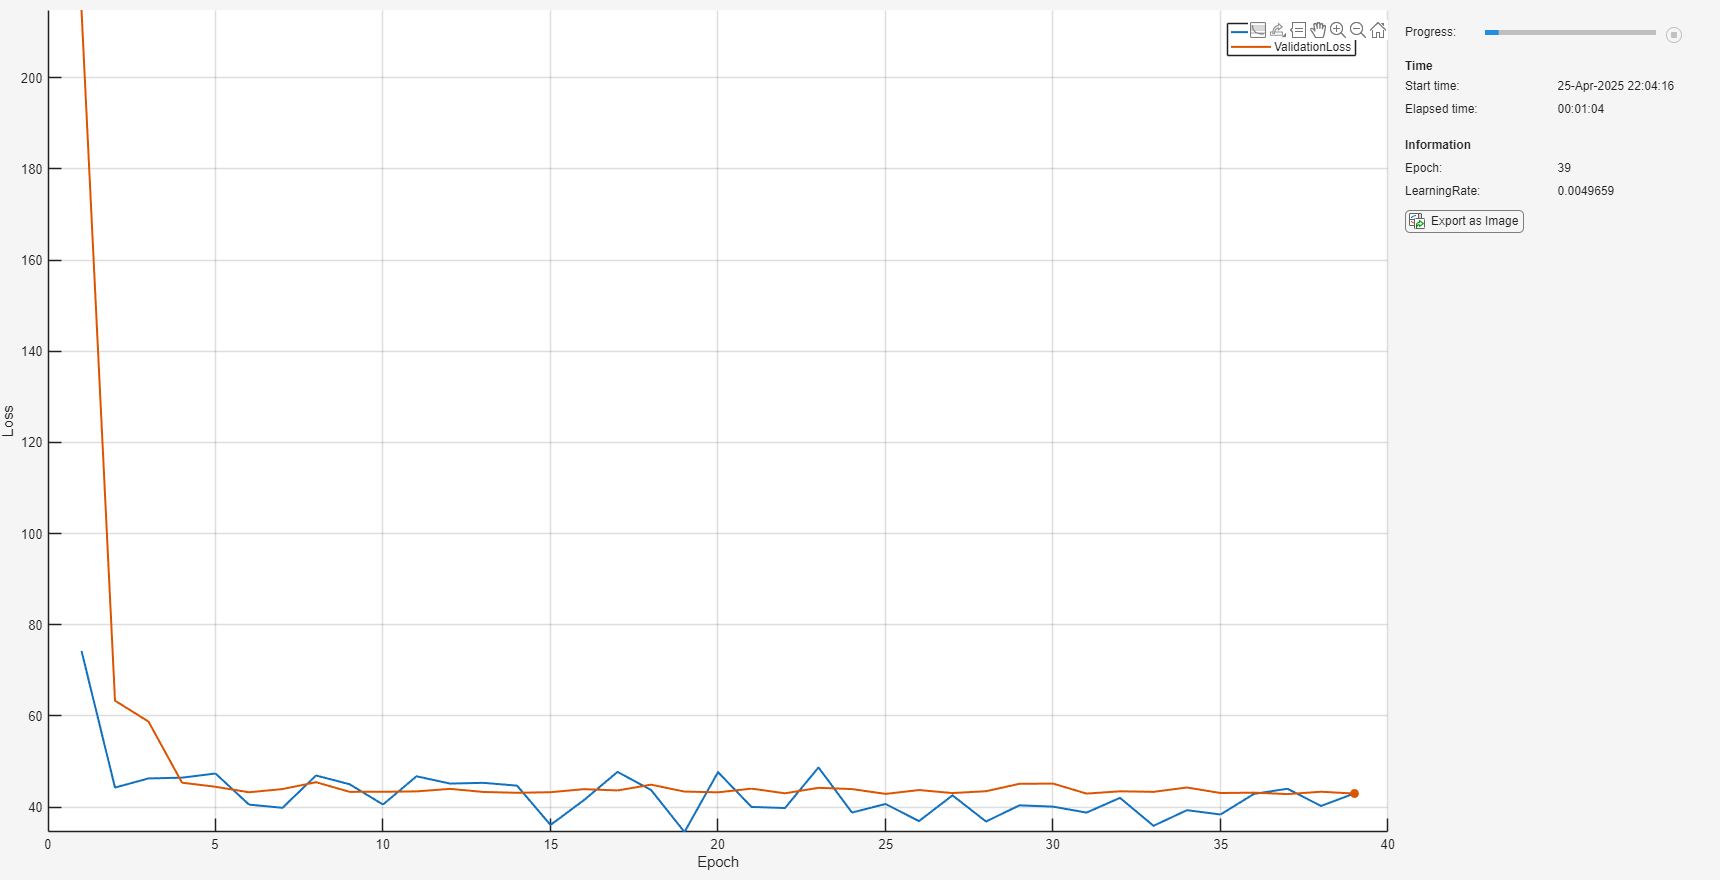

Manual training stop at epoch 40.


FFnet =   dlnetwork with properties:

         Layers: [7×1 nnet.cnn.layer.Layer]
    Connections: [6×2 table]
     Learnables: [6×3 table]
          State: [2×3 table]
     InputNames: {'input'}
    OutputNames: {'tanh'}
    Initialized: 1
  View summary with summary.

argsFFNNtrain.Verbose             = true;
argsFFNNtrain.MaxEpochs           = 500;
argsFFNNtrain.MiniBatchSize       = 128; % This must be adaptive during training for better fitting and generalization
argsFFNNtrain.ValidationPatience  = 50;

% FFnet = FFNNtrain(argsFFNNtrain)

argsFFNNtrain.HuberThreshold      = 10;
output_variance = var(dlY_tr, 0, 2);
output_variance(1:4) = mean(output_variance(1:4));
argsFFNNtrain.ErrorWeights        = 1;%./output_variance;

FFnet = FFNNtrain_custom(argsFFNNtrain)


if save_net
    save('ImitationLearning\ActualArchitecture\FFnet.mat', "FFnet")
end

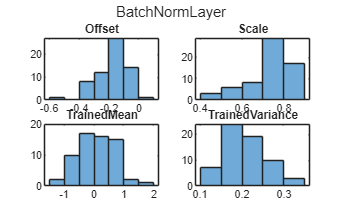

figure
subplot(2, 2, 1)
histogram(FFnet.Layers(3).Offset)
title('Offset')
subplot(2, 2, 2)
histogram(FFnet.Layers(3).Scale)
title('Scale')
subplot(2, 2, 3)
histogram(FFnet.Layers(3).TrainedMean)
title('TrainedMean')
subplot(2, 2, 4)
histogram(FFnet.Layers(3).TrainedVariance)
title('TrainedVariance')
sgtitle('BatchNormLayer')

## Summary

trainPerformance = dlfeval(@FFNNLoss, FFnet, dlX_tr, dlY_tr, 'validation', argsFFNNtrain.HuberThreshold, argsFFNNtrain.ErrorWeights);
valPerformance = dlfeval(@FFNNLoss, FFnet, dlX_val, dlY_val, 'validation', argsFFNNtrain.HuberThreshold, argsFFNNtrain.ErrorWeights);

disp(['Rendimiento en el conjunto de entrenamiento: ', num2str(trainPerformance)]);

Rendimiento en el conjunto de entrenamiento: 39.7871


disp(['Rendimiento en el conjunto de validación: ', num2str(valPerformance)]);

Rendimiento en el conjunto de validación: 42.8506


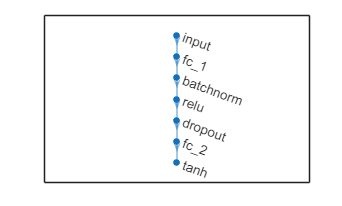


figure
plot(FFnet)

analyzeNetwork(FFnet);
summary(FFnet)

   Initialized: true
   Number of learnables: 1.8k
   Inputs:
      1   'input'   21 features


# Performance analysis

## Complete timeseries

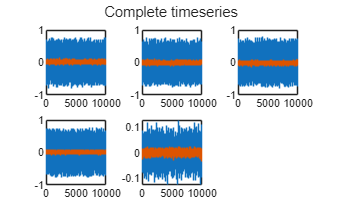

pred = extractdata(FFnet.predict(dlX));
figure
subplot(ceil(Noutputs/3), 3, 1)
stairs(1:Nsamples, Y(1, :))
hold on
stairs(1:Nsamples, pred(1, :))
hold off
for idx = 2:Noutputs
    subplot(ceil(Noutputs/3), 3, idx)
    stairs(1:Nsamples, Y(idx, :))
    hold on
    stairs(1:Nsamples, pred(idx, :))
    hold off
end
sgtitle('Complete timeseries');

## Error histogram

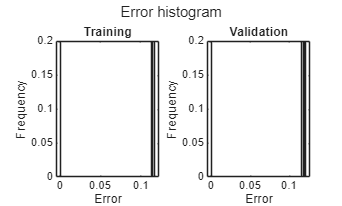

Y_tr_pred = extractdata(FFnet.predict(dlX_tr));
Y_val_pred = extractdata(FFnet.predict(dlX_val));

figure
subplot(1, 2, 1)
histogram(mean((Y_tr_pred - Y_tr).^2, 2), 1000, 'Normalization', 'probability')
title("Training")
xlabel("Error");
ylabel("Frequency")

subplot(1, 2, 2)
histogram(mean((Y_val_pred - Y_val).^2, 2), 1000, 'Normalization', 'probability')
title("Validation")
xlabel("Error");
ylabel("Frequency")

sgtitle('Error histogram');

## Regression

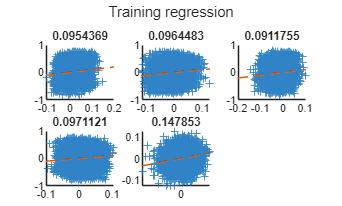

% xlabel("Predicted")
% ylabel("Actual")
% title("Correlation")

figure
title("Training")
subplot(ceil(Noutputs/3), 3, 1)
scatter(Y_tr_pred(1, :), Y_tr(1, :), "+")
title(corr(Y_tr_pred(1, :)', Y_tr(1, :)'))
hold on
ref_line = refline(1, 0);
ref_line.LineStyle = '--';
hold off
for idx = 2:Noutputs
    subplot(ceil(Noutputs/3), 3, idx)
    scatter(Y_tr_pred(idx, :), Y_tr(idx, :), "+")
    title(corr(Y_tr_pred(idx, :)', Y_tr(idx, :)'))
    hold on
    ref_line = refline(1, 0);
    ref_line.LineStyle = '--';
    hold off
end
sgtitle('Training regression');

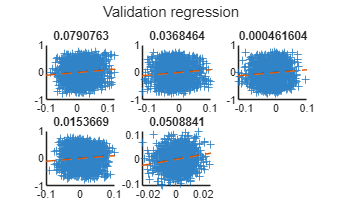


figure
subplot(ceil(Noutputs/3), 3, 1)
scatter(Y_val_pred(1, :), Y_val(1, :), "+")
title(corr(Y_val_pred(1, :)', Y_val(1, :)'))
hold on
ref_line = refline(1, 0);
ref_line.LineStyle = '--';
hold off
for idx = 2:Noutputs
    subplot(ceil(Noutputs/3), 3, idx)
    scatter(Y_val_pred(idx, :), Y_val(idx, :), "+")
    title(corr(Y_val_pred(idx, :)', Y_val(idx, :)'))
    hold on
    ref_line = refline(1, 0);
    ref_line.LineStyle = '--';
    hold off
end
sgtitle('Validation regression');

## Weight matrix analysis

Learnables = FFnet.Learnables

Learnables = 6×3 table
       Layer       Parameter         Value     
    ___________    _________    _______________
    "fc_1"         "Weights"    {63×21 dlarray}
    "fc_1"         "Bias"       {63×1  dlarray}
    "batchnorm"    "Offset"     {63×1  dlarray}
    "batchnorm"    "Scale"      {63×1  dlarray}
    "fc_2"         "Weights"    { 5×63 dlarray}
    "fc_2"         "Bias"       { 5×1  dlarray}

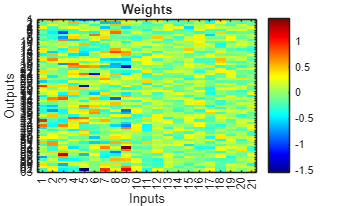

Learnables = Learnables.Value;

weights_input_hidden = extractdata(Learnables{1});

figure;
imagesc(weights_input_hidden);
colorbar;
colormap("jet");
title('Weights');
xlabel('Inputs');
ylabel('Outputs');
xticks(1:size(weights_input_hidden, 2));
yticks(1:size(weights_input_hidden, 1));

Near zero weights

weights_treshold = 0.01 * max(abs(weights_input_hidden(:)))

weights_treshold = 0.0156

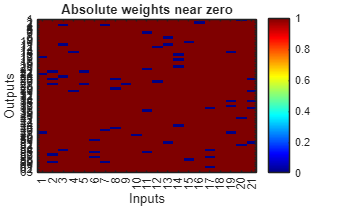

weights_input_hidden(abs(weights_input_hidden) <= weights_treshold) = 0;
weights_input_hidden(abs(weights_input_hidden) > weights_treshold) = 1;

figure;
imagesc(weights_input_hidden);
colorbar;
colormap("jet");
title('Absolute weights near zero');
xlabel('Inputs');
ylabel('Outputs');
xticks(1:size(weights_input_hidden, 2));
yticks(1:size(weights_input_hidden, 1));